# **ISS Live Script**

This Matlab Live Scripts summarizes the functions developed in order to analyse the spatial profiles derived from ISS. However, they can be applied to other spatial technologies, since the only requirement they present is the spatial distribution of genes in 2D, together with a DAPI background image representing the nuclei. 

## Loading the data

The path to the file containing the spatial expression of our genes of interest is saved in decoded_file. The background used, in our case DAPI, is saved in **image**. We extract the coordinates from the decoded_file using the function **ISS_getspots** and we save it on a SPOTS object. This SPOTS object contains the main information regarding Gene expression, its location, background image and output location. 

decoded_file = 'G:\DIPG pciseq\Sample2\QT_0.4_details_noNNNN_goodS2.csv';
image = 'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif';    % important for size
scale=1;
%% do not modify
% load
SPOTS=ISS_getspots(decoded_file);
SPOTS.image=image;
SPOTS.scale=scale;
SPOTS.output_directory='G:\outputfolder';
mkdir(SPOTS.output_directory);



## Gene Density maps


%ISS_GeneDensity plots the density of 1 gene
genes_density = {'SIRT2'}; 
bandwid = 200;   % in original scale
ISS_GeneDensity(SPOTS, genes_density, bandwid)




Overay 


%ISS_OverlayTwoDensities overlays 2 densities

genes_density = {'SIRT2', 'WASF1'};       % first in red, second in cyan
ISS_OverlayTwoDensities(SPOTS,genes_density,bandwid);


## Dissimilarity test 

% ISS_DissimilarityTest test for dissimilarity
    %varargin1 is minimum number of genes per cell
    % varargin2 is hexbin size
 ISS_DissimilarityTest(SPOTS,20);

## **Find Neighbors **

 ISS_FindNeighbors_screen_randomization(SPOTS)

## Search AND regions

ANDgenes= {'SIRT2', 'WASF1'}; 
ISS_SearchANDRegions(SPOTS,ANDgenes);

## Search for regions with Similarity

transcripts={'SIRT2', 'WASF1'};

ISS_A_B_neighbors(SPOTS,transcripts);

# **Segmentation techniques**

## Segmenting cells

percent=95;
[CellMap,blobs,XY]=ISS_DAPI_segmentation(SPOTS,percent);


%XY=fliplr(vertcat(regionprops(CellMap).Centroid));

ISS_plotCellReads(SPOTS,CellMap)

[TOTAL,EXPRESSIONMAT,CELS]= ISS_assign_gene_to_cell(SPOTS,CellMap,XY);

## Creating overlapping means

We include on 2nd position distance and on 3rd radius

[OUTPUT] =ISS_OverlappingBins(SPOTS,800,800)

## RGB-Tsne representations

### **Tsne representation **

hexbin_size=40;
minimum_expression=100

minimum_expression = 100

genes = 27×1 cell array
    {'AGT'    }
    {'APOE'   }
    {'AQP4'   }
    {'ARC'    }
    {'ASCL1'  }
    {'ATP1A2' }
    {'BCAS1'  }
    {'BMPER'  }
    {'CCND1'  }
    {'EDNRB'  }
    {'EGR1'   }
    {'FYN'    }
    {'GFAP'   }
    {'GPC3'   }
    {'GPR17'  }
    {'HOPX'   }
    {'HSPB8'  }
    {'KLRC2'  }
    {'MEST'   }
    {'NFASC'  }
    {'PCP4'   }
    {'PDGFRA' }
    {'RAB33A' }
    {'RGR'    }
    {'SIRT2'  }
    {'SPARCL1'}
    {'WASF1'  }


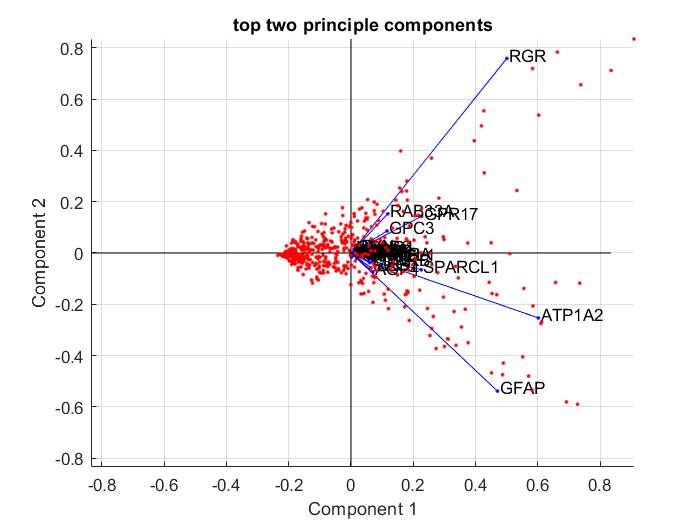


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    1.298854e+01 |    1.771521e-02 |
|       40 |    1.296239e+01 |    1.702860e-02 |
|       60 |    1.316071e+01 |    1.922228e-02 |
|       80 |    1.351010e+01 |    1.909357e-02 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    2.020696e+00 |    4.410113e-03 |
|      120 |    4.759204e-01 |    2.406984e-03 |
|      140 |    4.383109e-01 |    2.789754e-04 |
|      160 |    4.283076e-01 |    2.005248e-04 |
|      180 |    4.243228e-01 |    2.052035e-04 |
|      200 |    4.210977e-01 |    1.461923e-04 |
|      220 |    4.

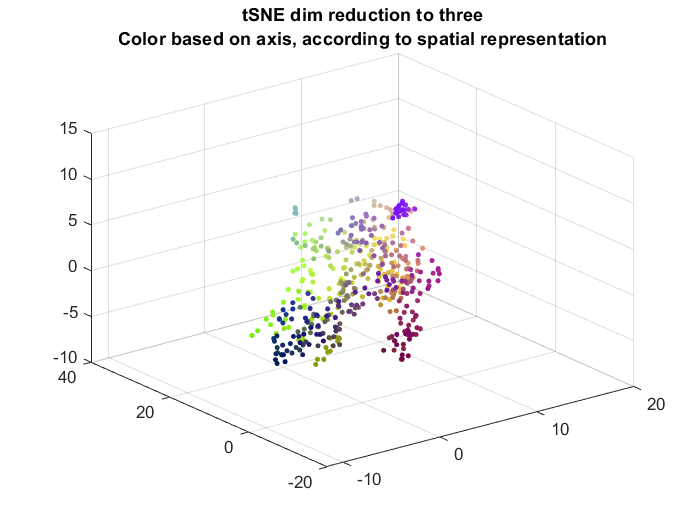

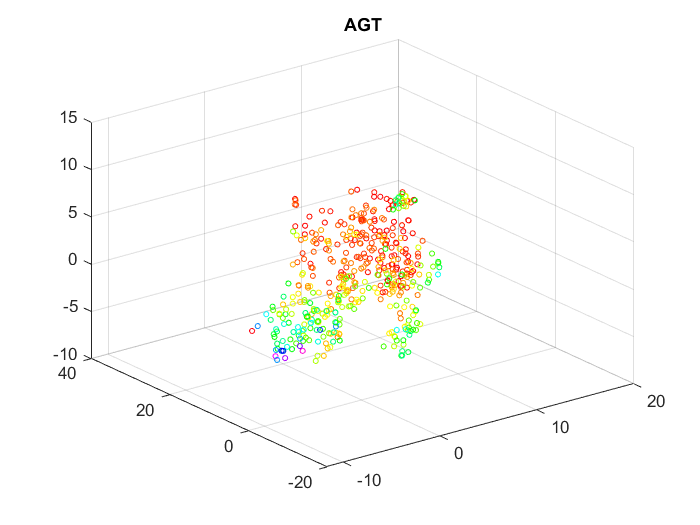

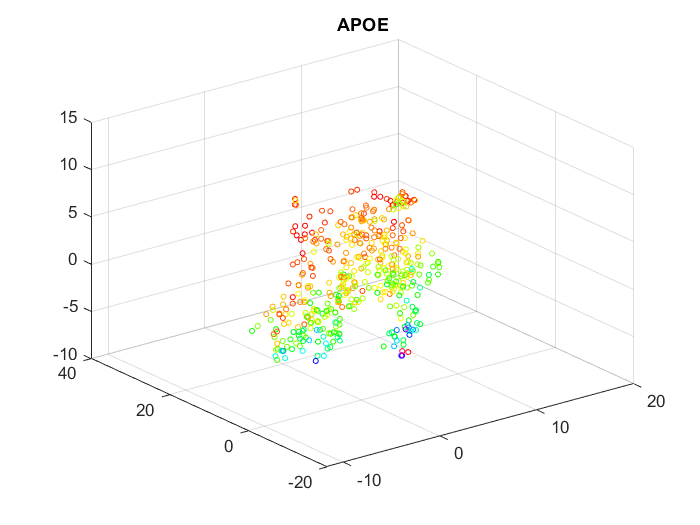

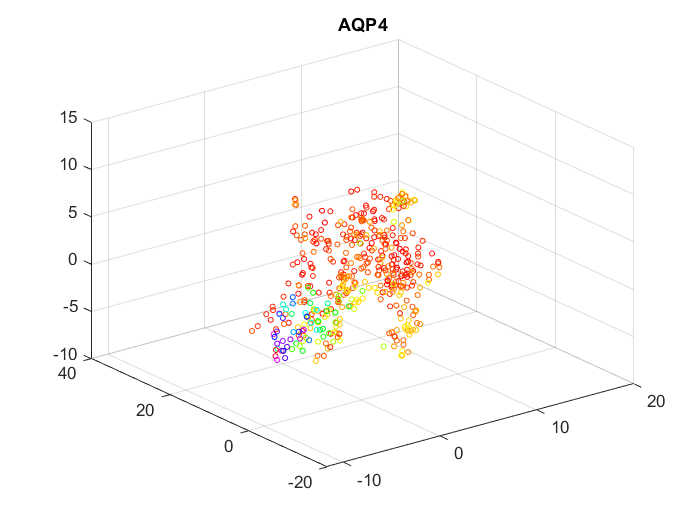

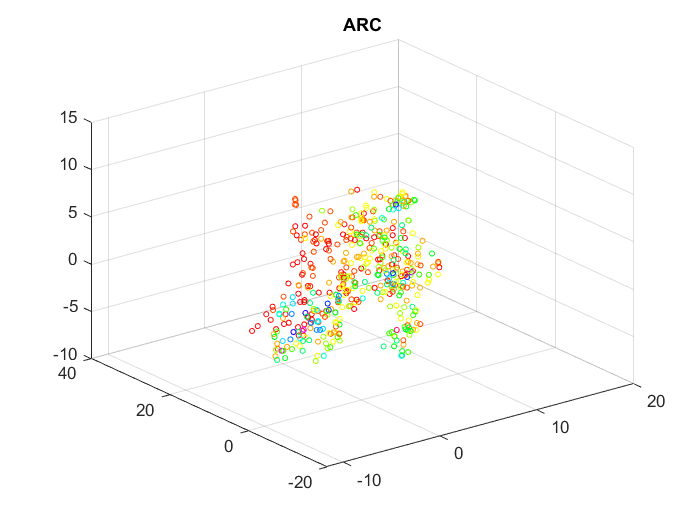

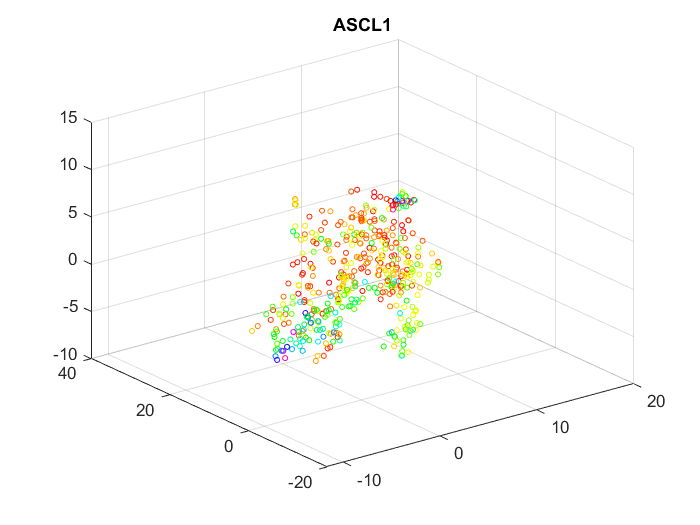

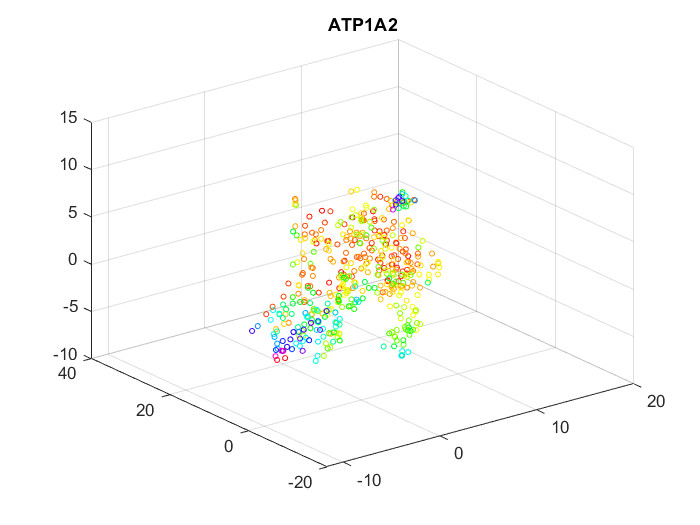

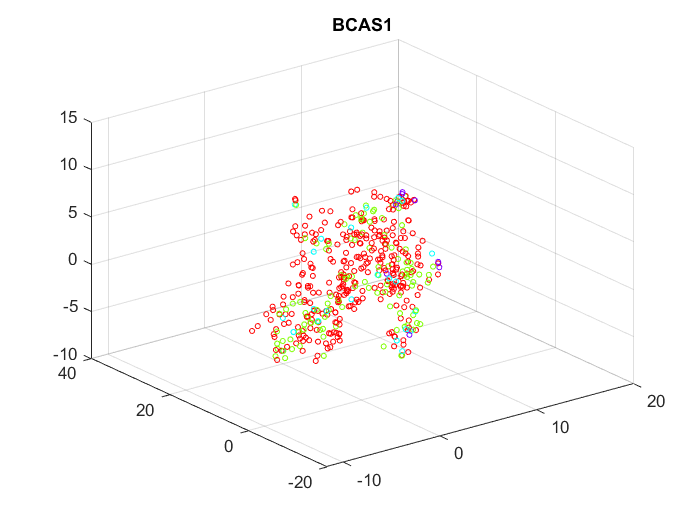

ISS_tsneRGB(OUTPUT,SPOTS,minimum_expression); %EXPRESSIONMAT, SPOTS

# Working with expression matrix 

This includes segmented data and binned data

## Clustering data

CELLSHIERARCHICAL= ISS_hierarchical_clustering(OUTPUT,SPOTS,6)


## PCISEQ

This part of PCIseq allows you to select 

BigDapiImage = imread(SPOTS.image);
figure(707);
imagesc(min(BigDapiImage,prctile(BigDapiImage(:),98)));
colormap(bone);
set(gca, 'YDir', 'normal');
[~, xpoly, ypoly] = roipoly;


Remember to load o to path

SPOTS.CellCallRegionYX=[ypoly,xpoly];




load E:\pciSeq\Data\AllSections\gSetCA1all.mat;
%CLUSTERED DATA ~ human cortex 
gSet.GeneExp=readmatrix('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
nam=readcell('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
namclust=readcell('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
gSet.GeneExp=gSet.GeneExp(:,2:end);
gSet.GeneExp=gSet.GeneExp';
gSet.GeneName=nam(2:end,1);
gSet.Class=namclust(1,2:end);
gSet.CellName=gSet.Class(1:size(gSet.Class,2));
gSet.nGenes=size(gSet.GeneExp,2);
gSet.nCells=size(gSet.GeneExp,1);



This is gSet for DIPG

load E:\pciSeq\Data\AllSections\gSetCA1all.mat;
gSet.GeneExp=readmatrix('G:\DIPG pciseq\expressionmatrix_selected.csv');
gSet.GeneExp=gSet.GeneExp(:,3:end);
nam=readcell('G:\DIPG pciseq\expressionmatrix_selected.csv');
gSet.GeneName=nam(2:end,2);
namclust=readcell('G:\DIPG pciseq\metadata_selected.csv');
gSet.Class=namclust(2:end,4);
gSet.CellName=gSet.CellName(1:size(gSet.Class,1));
gSet.nGenes=size(gSet.GeneExp,2);
gSet.nCells=size(gSet.GeneExp,1);
%THIS LINE IS FOR CONSIDERING CELL TYPE AS INDIVIDUAL CLASSES
%gSet.Class=gSet.CellName;





Running PCIseq itself

 CELLS = ISS_pciseq(SPOTS,CellMap,gSet)
gscatter(CELLS.pos(:,2),CELLS.pos(:,1),CELLS.name(:,1:end-1)')

Selection based on CELS

SELECTED.clusters=c;
SELECTED.pos=CELLS.pos(CELS,:);
SELECTED.name=CELLS.name(:,CELS);

[celltypecor,n,n,labels]=crosstab(SELECTED.name,SELECTED.clusters);

figure
XC=unique(SELECTED.clusters);
YC=unique(SELECTED.name);
h = heatmap(labels(:,2),labels(2:6,1),celltypecor(2:6,:))


#### Heatmap on PCISEQ

Plotting a heatmap of differentially expressed clusters

     1

     2

     3

     4

     5

     6



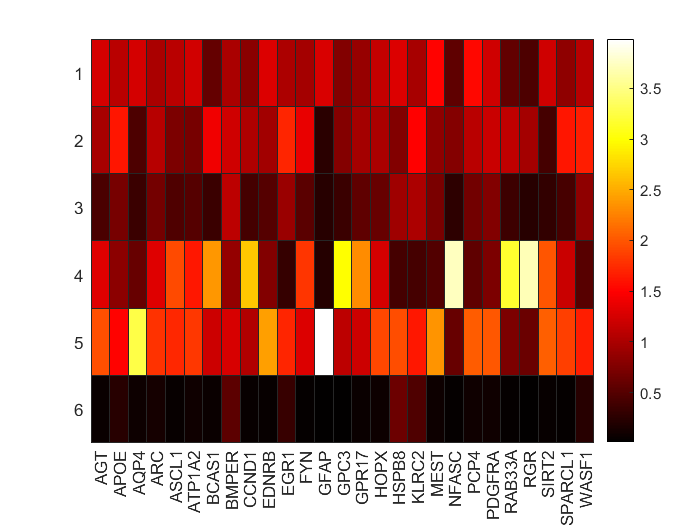

ISS_heatmap_cluster(OUTPUT,CELLSHIERARCHICAL.name')

%ISS_heatmap_cluster(EXPRESSIONMAT,SELECTED.name')

## ROI selection


output_directory='G:\Tools-master\Visualization tools\Analize Region of Interests\ROI';
roi_number=2;
%LAST TWO TERMS CAN BE IN OR OUR DEPENDING IF YOU WANT TO SELECT BY DENSITY
%(adding 'GPR17',100)
%OR DAPI 
[INROI,ROI_borders] = ISS_ROI_draw_onImage(SPOTS,output_directory,roi_number);

Now we select ROI based on density 

-THIS IS SOMETHING THAT CAN BE ADDED 

## **GRADIENT ANALYSIS**

We define a gradient expression based on a ROI defined by ourselves

limits=800;
bandwidth=100;
ISS_gradients(CELLS,limit,bandwidth)
